`Implementation ch. 2 Costa's thesis: STOCHASTIC MODELLING OF NEMATODES BEHAVIOUR ACROSS SPECIES (RANDOM WALK)`

`In the following, the mdoel provides the simplest quantitative approach for capturing the observed behavioral statistics of the worm. The only considered elements are the ORIENTATIONAL & TRANSATIONAL dyanmics of the trajectory. `

`The model presents 3 ``independent`` components: `

- `Speed fluctuations`` relaxing to a set point on a few sec time scale`

- `Orientation fluctuations`` with drift `

- `Stochastic switching`` between forward and reverse modes `

`This describes the statistcis of the trajectory. `

`Here the reorientation mechanism are ``excluded`` from the data.  `

`Steps:`

- `Compute statistics for: individual ``isolated`` vs individual in ``collective environemnt`` for different strains and species`

- `Look at parameter space for all individuals `

- `Implement model simulation`

- `    how do parameter statistics compare across isolated and social environment? `

- `    are collective strains/species packed tohgether in the parameter space `

- `    simulation of multiple individuals with trajectory statistcis and no taxi `

- `        can both models generate collective behaviours? `

`Random walk in this model can be decomposed in speed, turning and reversal dynamics.`

`--------------------------------------------------------------------------------------`

`Data ideally required: `

- `One condition for all strains/species and for isolated vs collective environment: food quantity `

- `Isolated individual full body marker (fluorescent) `

- `Group of 40 individuals with 1-3 red full body, and rest heads (fluorescent)`

`--------------------------------------------------------------------------------------`

clear all; close all; clc;
set(0,'DefaultAxesFontSize', 20)

Data available for now: 

- npr-1

-     isolated: 13

-     collective: 13

- N2

-     isolated: 10

-     collective: 9

% FLUORESCENT DATA Red ISOLATED CONDITIONS 
strain = 1; 
if strain == 1
    cd("/Users/erusconi/Documents/Analysis_Data/project_A/data/fluorescence/isolated_conditions/skeleton_npr1");  % npr1  
end 
if strain == 2
    cd("/Users/erusconi/Documents/Analysis_Data/project_A/data/fluorescence/isolated_conditions/skeleton_N2");  % N2  
end 
fds = fileDatastore('*.hdf5', 'ReadFcn', @importdata);   % here you can specify which ever file type you prefer 

skelFile = fds.Files;

numFiles = length(skelFile);

% Loop over all files reading them in and plotting them.
for k = 1 : numFiles
    name = sprintf('dataSet_%d', k);   
%     fprintf('Now reading file %s\n', skelFile{k});

    trajData.(name) = h5read(skelFile{k},'/trajectories_data');
    blobFeats.(name) = h5read(skelFile{k},'/blob_features');
    skeleton.(name)= h5read(skelFile{k}, '/skeleton');
end 


% FLUORESCENT DATA Red COLLECTIVE CONDITIONS 40
if strain == 1 
    cd("/Users/erusconi/Documents/Analysis_Data/project_A/data/fluorescence/collective_conditions/skeleton_npr1");   % npr1 
end
if strain == 2
    cd("/Users/erusconi/Documents/Analysis_Data/project_A/data/fluorescence/collective_conditions/skeleton_N2");   % N2
end 
fds2 = fileDatastore('*.hdf5', 'ReadFcn', @importdata);   % here you can specify which ever file type you prefer 

skelFile2 = fds2.Files;

numFiles2 = length(skelFile2);

% Loop over all files reading them in and plotting them.
for k = numFiles+1 : numFiles2+numFiles
    name = sprintf('dataSet_%d', k);   
%     fprintf('Now reading file %s\n', skelFile2{k-numFiles})

    trajData.(name) = h5read(skelFile2{k-numFiles},'/trajectories_data');
    blobFeats.(name) = h5read(skelFile2{k-numFiles},'/blob_features');
    skeleton.(name)= h5read(skelFile2{k-numFiles}, '/skeleton');
end

% BRIGHTFIELD DATA COLLECTIVE CONDITIONS 5
if strain ==1
    cd("/Users/erusconi/Documents/Analysis_Data/project_A/data/brightfield /skeleton_npr1");   % npr1 
end
if strain == 2
    cd("/Users/erusconi/Documents/Analysis_Data/project_A/data/brightfield /skeleton_N2");   % N2
end 
fds3 = fileDatastore('*.hdf5', 'ReadFcn', @importdata);   % here you can specify which ever file type you prefer 

skelFile3 = fds3.Files;

numFiles3 = length(skelFile3);

% Loop over all files reading them in and plotting them.
for k = numFiles2+numFiles+1 : numFiles2+numFiles3+numFiles
    name = sprintf('dataSet_%d', k);   
%     fprintf('Now reading file %s\n', skelFile2{k-numFiles})

    trajData.(name) = h5read(skelFile3{k-(numFiles2+numFiles)},'/trajectories_data');
    blobFeats.(name) = h5read(skelFile3{k-(numFiles2+numFiles)},'/blob_features');
    skeleton.(name)= h5read(skelFile3{k-(numFiles2+numFiles)}, '/skeleton');
end



% % FLUORESCENT DATA Green COLLECTIVE CONDITIONS
% cd("/Users/erusconi/Documents/Analysis_Data/project_A/data/fluorescence/collective_conditions/head_npr1");   % npr1 
% % cd("/Users/erusconi/Documents/Analysis_Data/project_A/data/fluorescence/collective_conditions/skeleton_N2");   % N2
% fds3 = fileDatastore('*.hdf5', 'ReadFcn', @importdata);   % here you can specify which ever file type you prefer 
% 
% skelFileHead = fds3.Files;
% 
% numFilesHead = length(skelFileHead);
% 
% % Loop over all files reading them in and plotting them.
% for k = 1 : numFilesHead
%     name = sprintf('dataSet_%d', k);   
% %     fprintf('Now reading file %s\n', skelFile2{k-numFiles})
% 
%     trajDataGreen.(name) = h5read(skelFileHead{k},'/trajectories_data');
%     blobFeatsGreen.(name) = h5read(skelFileHead{k},'/blob_features');
%     skeletonGreen.(name)= h5read(skelFileHead{k}, '/skeleton');
% end 


- `Video FPS: 3`

- `x,y coordinates units of measure: pixel`

- `conversion factor: 19.5 mm/pixel`

`For the 5 individuals case it might be different conversion values. Check on the metadata`

`Keep only trajectories that are longer then min_length(=50) `

`worm_index_present.(name) contains all indexes in dataSet = name `

`row_worm_i(name) contains the rows in trajData.(name) in which the worm index selected is present `

min_length = 50;

for k = 1:numFiles+numFiles2+numFiles3
    name = sprintf('dataSet_%d', k); %
    worm_index_present.(name) = unique(trajData.(name).worm_index_joined); %
    worm_index_kept(1).(name) = []; %
    row_worm_i(1).(name) = [];  %

    for i = 1:size(worm_index_present.(name),1)      % loop through each individual %
        row_worm_i.(name) = [row_worm_i.(name); {find(trajData.(name).worm_index_joined == worm_index_present.(name)(i))}];
        worm_index_kept.(name) = [worm_index_kept.(name); worm_index_present.(name)(i)]; 
        if size(row_worm_i.(name){end},1) < min_length
            row_worm_i.(name){end} = []; 
            worm_index_kept.(name)(end) = [];
        end 
    end 
    row_worm_i.(name) = row_worm_i.(name)(~cellfun('isempty',row_worm_i.(name)));    % delete all cells that are empty 
end 
rows_worm_i_used = row_worm_i; 

`To print after the number of individuals used to compute the measurments and the total number of frames `

n_events_isolated_name = []; 
frames_isol_name = []; 
n_events_colective_name =[]; 
frames_col_name = []; 
n_events_semicolective_name =[]; 
frames_semicol_name = []; 

for k = 1:numFiles
    name = sprintf('dataSet_%d', k); %
    n_events_isolated_name = [n_events_isolated_name; size(worm_index_kept.(name),1)];
    for i=1:size(worm_index_kept.(name),1)
        frames_isol_name = [frames_isol_name; size(row_worm_i.(name){i},1)];
    end 
end
tot_n_even_isol = sum(n_events_isolated_name);
tot_kept_frames_isol = sum(frames_isol_name);

for k = numFiles+1:numFiles+numFiles2
    name = sprintf('dataSet_%d', k); 
    n_events_colective_name = [n_events_colective_name; size(worm_index_kept.(name),1)];
    for i=1:size(worm_index_kept.(name),1)
        frames_col_name = [frames_col_name; size(row_worm_i.(name){i},1)];
    end 
end 
tot_n_even_col = sum(n_events_colective_name);
tot_kept_frames_col = sum(frames_col_name);

for k = numFiles2+numFiles+1 : numFiles2+numFiles3+numFiles
    name = sprintf('dataSet_%d', k); 
    n_events_semicolective_name = [n_events_semicolective_name; size(worm_index_kept.(name),1)];
    for i=1:size(worm_index_kept.(name),1)
        frames_semicol_name = [frames_semicol_name; size(row_worm_i.(name){i},1)];
    end 
end 
tot_n_even_semicol = sum(n_events_semicolective_name);
tot_kept_frames_semicol = sum(frames_semicol_name);

legend_isol = sprintf("Isolated: %d",tot_n_even_isol); 
legend_col = sprintf("Collective-40: %d",tot_n_even_col);
legend_semicol = sprintf("Collective-5: %d",tot_n_even_semicol);

`Subsampling the trajectories every n points `

% n = 10; 
% for k = 1:numFiles+numFiles2
%     name = sprintf('dataSet_%d', k); 
%     row_worm_i_subsample(1).(name) = [];  
% 
%     for i = 1:size(worm_index_kept.(name),1)
%         row_worm_i_subsample.(name){i,1} = row_worm_i.(name){i}(1:n:end);
%     end 
% end 
% 
% rows_worm_i_used = row_worm_i_subsample; 


$$\phi \left(t\right):\textrm{bearing}$$


- `Centrioid direction of movement`

- `This is the angle between direction of movment and x axis`

`Part of the answer is taken from `[`here`](https://it.mathworks.com/matlabcentral/answers/180131-how-can-i-find-the-angle-between-two-vectors-including-directional-information#:~:text=angle%20%3D%20atan2d(x1*y2,*x2%2By1*y2)%3B)

va = [1 0]; 
pOrder = 2;
window = 4;     % with window = 4, we have 2 points to left and 2 to right

for k = 1:numFiles+numFiles2+numFiles3
    name = sprintf('dataSet_%d', k); 
    velocity_centr(1).(name) = [];
    phi(1).(name) = [];

    for i = 1:size(worm_index_kept.(name),1)      % loop through each individual 
        xy_coor_momen = mean(skeleton.(name)(1:2,1:49,rows_worm_i_used.(name){i,1}),2).*19.5*0.001; 
        xy_coor.(name){i,1} = reshape(xy_coor_momen,2,size(rows_worm_i_used.(name){i},1))';
        xy_coor_momen = [];
        maxFrame = size(rows_worm_i_used.(name){i},1);
        
        % polynomial fitting for the xy-coord and estimate smoothed velocity 
        for j = 1:2      % loop through x and y 
            for frame = 1 + window/2:maxFrame - window/2  %loop over frames
                dataWin = xy_coor.(name){i}(frame-window/2:frame+window/2,j);    % data in the window considered around the frame to be filtered 
                p = polyfit(1:window+1, dataWin, pOrder);       % polinomial of order pOrder fitted on the data window 
                
                nl = 1+window/2;    % point that is evaluated 
                dataFilt.(name){i,1}(frame,j) = polyval(p,nl);     % velauate the polynomial in the original x value 
                velocity_centr.(name){i,1}(frame,j) = polyval(polyder(p),nl).*3;   % velocity in pixels/seconds         CHECK FPS FOR ISOLATED!!! 
                datadot2Filt.(name){i,1}(frame,j) = polyval(polyder(polyder(p)),nl);
            end
            dataWin = []; 
        end 
    end 
    
    
    for i = 1:size(worm_index_kept.(name),1)
        rows_worm_i_used.(name){i}(1:window/2) = [];
        rows_worm_i_used.(name){i}(end+1-window/2:end) = []; 
        dataFilt.(name){i}(1:window/2,:) = [];
        velocity_centr.(name){i}(1:window/2,:) = [];
    
        % estimate speed 
        speed_centr.(name){i,1} = sqrt(sum((velocity_centr.(name){i}).^2,2));
        
    
        % estimate angle phi (orientation centrioid vector) 
        for j = 1:size(velocity_centr.(name){i},1)
            vb = velocity_centr.(name){i}(j,:)/speed_centr.(name){i,1}(j); 
            
            phi.(name){i,1}(j,1) = atan2d(vb(1)*va(2)-vb(2)*va(1),vb(1)*va(1)+vb(2)*va(2));

            % changes the range from [-180, 180] to [0 360]
            if phi.(name){i,1}(j,1) < 0 
                phi.(name){i,1}(j,1) =  phi.(name){i,1}(j,1) + 360; 
            end 
        end 
    end 
end 

`To differentiate forward or backward movment `

% speed_sign = speed_centr; 
% 
% for k = 1:numFiles+numFiles2+numFiles3
%     name = sprintf('dataSet_%d', 1 );
%      for i = 1:size(worm_index_kept.(name),1) 
%           ang_diff = abs(diff(phi.(name){i})) ; 
%           for j =1:size(ang_diff,1)
%             reverse.(name){i,1}(j,1) = boolean((ang_diff(j) > 135) & (ang_diff(j) < 215)); 
%             if reverse.(name){i,1}(j) == 1
%                 speed_sign.(name){i,1}(j) = -speed_centr.(name){i}(j);
%             end
%           end 
%           
%      end 
%      ang_diff = []; 
% end 

MA CHE COGLIONA!  mi basta usare delta psi porca la miseria 

`Note: if in xy_coor you average over all 49 points you get the centrioid, while if you average on the middle points (20:30) you get the center of mass. The two descriptions give overall similar results, but they are different! `

`Comparison smoothed and non-smoothed data: Plot smoothed trajectory (dataFilt) and smoothed velocity (datadotFilt) for individual ind in red, and non-smoothed data in blue`

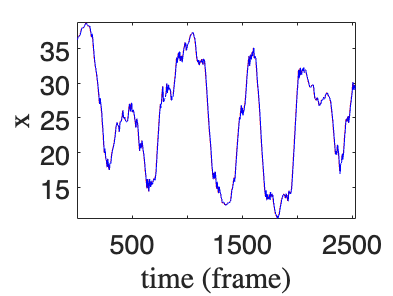

% % plot of x-coordinate in time 
name = sprintf('dataSet_%d', 1 );
ind = 1;

figure 
plot(dataFilt.(name){ind}(:,1),'r')
hold on 
plot(xy_coor.(name){ind}(:,1),'b')
xlabel('time (frame)','Interpreter','latex')
ylabel('x','Interpreter','latex')
axis tight 

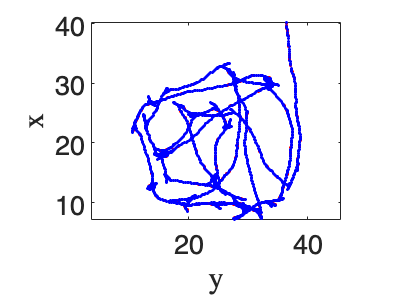


figure
% plot of x,y-coordinate in xy space 
figure 
plot(dataFilt.(name){ind}(:,1),dataFilt.(name){ind}(:,2), 'r.-')
hold on 
plot(xy_coor.(name){ind}(:,1), xy_coor.(name){ind}(:,2),'b.-')
axis equal 
xlabel('y','Interpreter','latex')
ylabel('x','Interpreter','latex')

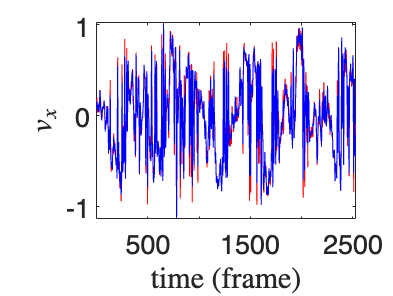


% plot of v_x in time 
figure 
plot(velocity_centr.(name){ind}(:,1),'r')
hold on 
plot(diff(trajData.(name).coord_x(rows_worm_i_used.(name){ind})).*3*19.5*0.001,'b')
xlabel('time (frame)','Interpreter','latex')
ylabel('$v_x$','Interpreter','latex')
axis tight

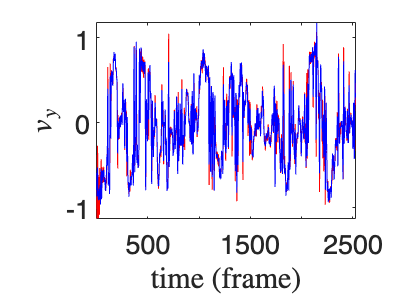


% plot of v_y in time 
figure 
plot(velocity_centr.(name){ind}(:,2),'r')
hold on 
plot(diff(trajData.(name).coord_y(rows_worm_i_used.(name){ind})).*3*19.5*0.001,'b')
xlabel('time (frame)','Interpreter','latex')
ylabel('$v_y$','Interpreter','latex')
axis tight

% 

% 
% % plot of v_x,v_y in v_x,v_y plane 
% figure 
% plot(velocity_centr.(name){ind}(:,1),velocity_centr.(name){ind}(:,2), 'r.')
% hold on 
% plot(diff(trajData.(name).coord_x(rows_worm_i_used.(name){ind})).*9, diff(trajData.(name).coord_y(rows_worm_i_used.(name){ind})).*9,'b.')
% axis equal 
% xlabel('$v_x$','Interpreter','latex')
% ylabel('$v_y$','Interpreter','latex')
% % 
% % plot speed in time 
% figure 
% plot(speed_centr.(name){ind},'b')
% xlabel('time (frame)','Interpreter','latex')
% ylabel('$s$','Interpreter','latex')
% axis tight
%  
% % plot histogram speed trajectory ind
% figure
% histogram(speed_centr.(name){ind},100,'Normalization','probability')
% xlabel('Speed','Interpreter','latex')
% ylabel('prob.','Interpreter','latex')

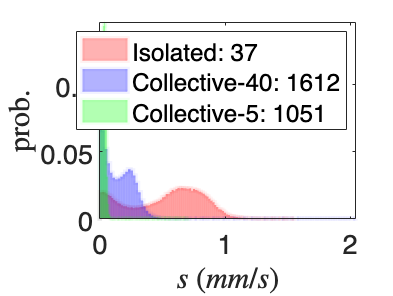

speed_centr_mat_isolated = []; 
speed_centr_mat_collective = []; 
speed_centr_mat_semicollective = []; 

for k = 1:numFiles
    name = sprintf('dataSet_%d', k);
    speed_centr_mat_isolated = [speed_centr_mat_isolated; cell2mat(speed_centr.(name))];
end 
for k = numFiles+1:numFiles+numFiles2
    name = sprintf('dataSet_%d', k);
    speed_centr_mat_collective = [speed_centr_mat_collective; cell2mat(speed_centr.(name))];
end 
for k = numFiles2+numFiles+1 : numFiles2+numFiles3+numFiles
    name = sprintf('dataSet_%d', k);
    speed_centr_mat_semicollective = [speed_centr_mat_semicollective; cell2mat(speed_centr.(name))];
end 

% plot histogram speed all trajectories
figure
h1 = histogram(speed_centr_mat_isolated,100,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[1 0 0],'EdgeAlpha',0.05,'EdgeColor',[1 0 0],'LineWidth',3);       %red
hold on 
h2 = histogram(speed_centr_mat_collective,100,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[0 0 1],'EdgeAlpha',0.05,'EdgeColor',[0 0 1],'LineWidth',3);     %blue
h3 = histogram(speed_centr_mat_semicollective,100,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[0 1 0],'EdgeAlpha',0.05,'EdgeColor',[0 1 0],'LineWidth',3);       % green
axis tight
xlabel('$s$ $(mm/s)$','Interpreter','latex')
ylabel('prob.','Interpreter','latex')
% xlim([0, 4]);
% ylim([0, 0.4]);
% legend_isol = sprintf("Isolated: %d",tot_n_even_isol); 
% legend_col = sprintf("Collective: %d",tot_n_even_col);
% legend_semicol = sprintf("Semi-collective: %d",tot_n_even_semicol);
legend({legend_isol, legend_col,legend_semicol})

`By looking through the smoothed trajectory compared to the original one we can see that the points most affected are the ones during the dwelling part of the trajectory and not the ones during the long distance movement. `

`By looking through the trajectory and seeing when the worm transitions from local dwelling to global exploration we can see that the angles actually coincide! So everything is good! I was expecting the results to look more like Antonio's analysis, but the conditions are very different (food, social) so the time series should be different. It is interesting that the probability distributions aren't actually that different! `

`Check angle distribution for all individuals `

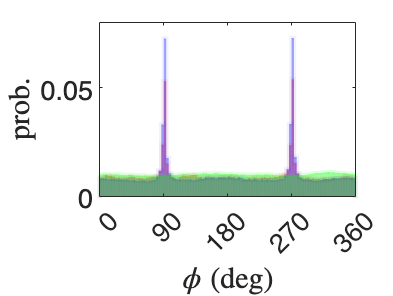

phi_mat_isolated = []; 
phi_mat_collective = [];
phi_mat_semicollective = []; 
for k = 1:numFiles
    name = sprintf('dataSet_%d', k); 
    phi_mat_isolated = [phi_mat_isolated; cell2mat(phi.(name))];
end 
for k = numFiles + 1:numFiles2+numFiles
    name = sprintf('dataSet_%d', k); 
    phi_mat_collective = [phi_mat_collective; cell2mat(phi.(name))];
end 
for k = numFiles2+numFiles+1 : numFiles2+numFiles3+numFiles
    name = sprintf('dataSet_%d', k); 
    phi_mat_semicollective = [phi_mat_semicollective; cell2mat(phi.(name))];
end 
phi_mat_isolated(isnan(phi_mat_isolated)) = []; 
phi_mat_collective(isnan(phi_mat_collective)) = []; 
phi_mat_semicollective(isnan(phi_mat_semicollective)) = []; 


figure
histogram(phi_mat_isolated,100,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[1 0 0],'EdgeAlpha',0.05,'EdgeColor',[1 0 0],'LineWidth',3)    %red
hold on 
histogram(phi_mat_collective,100,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[0 0 1],'EdgeAlpha',0.05,'EdgeColor',[0 0 1],'LineWidth',3)     %blue
histogram(phi_mat_semicollective,100,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[0 1 0],'EdgeAlpha',0.05,'EdgeColor',[0 1 0],'LineWidth',3)     %blue
xlim([0, 360]);
xticks(0:90:360);
xlabel('$\phi$ (deg)','Interpreter','latex')
ylabel('prob.','Interpreter','latex')

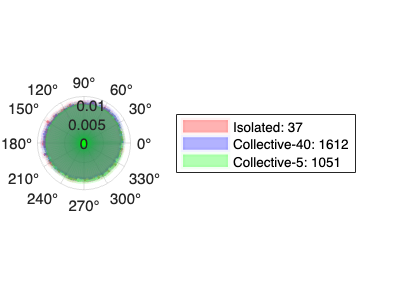


figure
polarhistogram(phi_mat_isolated,100,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[1 0 0],'EdgeAlpha',0.05,'EdgeColor',[1 0 0],'LineWidth',3)    %red
hold on 
polarhistogram(phi_mat_collective,100,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[0 0 1],'EdgeAlpha',0.05,'EdgeColor',[0 0 1],'LineWidth',3)     %blue
polarhistogram(phi_mat_semicollective,100,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[0 1 0],'EdgeAlpha',0.05,'EdgeColor',[0 1 0],'LineWidth',3)     %blue
% legend_isol = sprintf("Isolated: %d",tot_n_even_isol); 
% legend_col = sprintf("Collective: %d",tot_n_even_col);
% legend_semicol = sprintf("Semi-collective: %d",tot_n_even_semicol);
legend({legend_isol, legend_col,legend_semicol})

`Plot histogram per experiment. Contains phi distribution for all individuals present in the datase_k comnputed for `

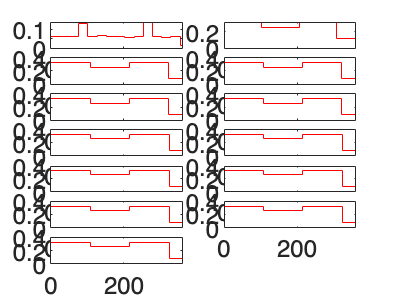

figure
for k=1:numFiles
    name = sprintf('dataSet_%d', k); 
    for i = 1:size(worm_index_kept.(name),1)
        phi_mat_isolated = [phi_mat_isolated; size(phi.(name){i},1)];
        phi_mat_isolated(isnan(phi_mat_isolated)) = []; 
    end 
    subplot(7,2,k) 
    
    histogram(phi_mat_isolated,100,'Normalization','probability','DisplayStyle','stairs','EdgeColor',[1 0 0])    %red
    xlim([0, 360]);
end

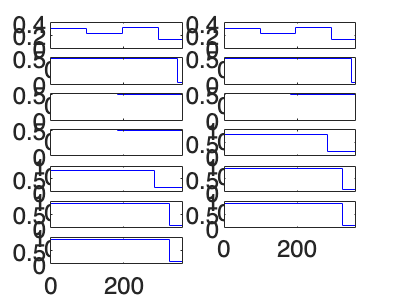


figure
for k=1+numFiles:numFiles+numFiles2
    name = sprintf('dataSet_%d', k); 
    for i = 1:size(worm_index_kept.(name),1)
        phi_mat_collective = [phi_mat_collective; size(phi.(name){i},1)];
        phi_mat_collective(isnan(phi_mat_collective)) = []; 
    end 
    subplot(7,2,k-numFiles) 
    
    histogram(phi_mat_collective,100,'Normalization','probability','DisplayStyle','stairs','EdgeColor',[0 0 1])     %blue
    xlim([0, 360]);
end

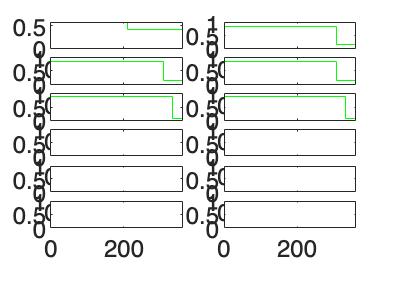


figure
for k = numFiles2+numFiles+1 : numFiles2+numFiles3+numFiles
    name = sprintf('dataSet_%d', k); 
    for i = 1:size(worm_index_kept.(name),1)
        phi_mat_semicollective = [phi_mat_semicollective; size(phi.(name){i},1)];
        phi_mat_semicollective(isnan(phi_mat_semicollective)) = []; 
    end 
    subplot(7,2,k-numFiles-numFiles2) 
    
    histogram(phi_mat_semicollective,100,'Normalization','probability','DisplayStyle','stairs','EdgeColor',[0 1 0])     %blue
    xlim([0, 360]);
end

`Plot speed time series for one individual `

% name = sprintf('dataSet_%d', 3);
% ind = 1;
% figure 
% plot(phi.(name){ind},'-')
% xlabel('time','Interpreter','latex')
% ylabel('$\phi$ (deg)','Interpreter','latex')
% axis tight 
% 
% figure 
% plot(speed_centr.(name){ind},'-')
% xlabel('time','Interpreter','latex')
% ylabel('speed','Interpreter','latex')   % fix units
% axis tight 

`Expectation: uniform distribution throguh all angles. `


$$\psi \left(t\right):\textrm{orientation}$$


- `to account for head-tail assymetry`

- `Is the vector pointing from centrioid to head `

for k = 1:numFiles+numFiles2+numFiles3
    name = sprintf('dataSet_%d', k); %
    vec_centr_head(1).(name) = [];
    psi(1).(name) = [];

    for i =1:size(worm_index_kept.(name),1)
        head = mean(skeleton.(name)(1:2,1:8,rows_worm_i_used.(name){i,1}),2);
        head = reshape(head,2,size(rows_worm_i_used.(name){i},1))';
        center_Mass = mean(skeleton.(name)(1:2,20:30,rows_worm_i_used.(name){i,1}),2); 
        center_Mass = reshape(center_Mass,2,size(rows_worm_i_used.(name){i},1))';
        vec_centr_head.(name){i,1} = head - center_Mass;
        for j = 1:size(vec_centr_head.(name){i},1)
            vb = vec_centr_head.(name){i}(j,:)/sqrt(sum(vec_centr_head.(name){i}(j,:)).^2);
            psi.(name){i,1}(j,1) = atan2d(vb(1)*va(2)-vb(2)*va(1),vb(1)*va(1)+vb(2)*va(2));
            vb = []; 
        end 
    end 
end 

`Check angle distribution`

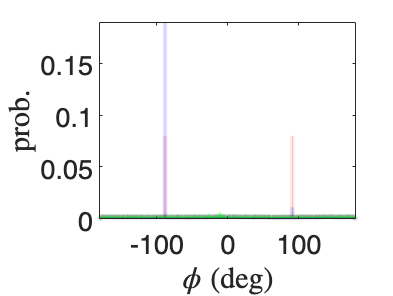

psi_mat_isolated = []; 
psi_mat_collective = [];
psi_mat_semicollective = [];

for k = 1:numFiles
    name = sprintf('dataSet_%d', k);
    psi_mat_isolated = [psi_mat_isolated; cell2mat(psi.(name))];
end 
for k = numFiles + 1:numFiles2+numFiles
    name = sprintf('dataSet_%d', k); 
    psi_mat_collective = [psi_mat_collective; cell2mat(psi.(name))];
end 
for k = numFiles2+numFiles+1 : numFiles2+numFiles3+numFiles
    name = sprintf('dataSet_%d', k); 
    psi_mat_semicollective = [psi_mat_semicollective; cell2mat(psi.(name))];
end 
psi_mat_isolated(isnan(psi_mat_isolated)) = [];
psi_mat_collective(isnan(psi_mat_collective)) = []; 
psi_mat_semicollective(isnan(psi_mat_semicollective)) = []; 


figure
histogram(psi_mat_isolated,500,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[1 0 0],'EdgeAlpha',0.05,'EdgeColor',[1 0 0],'LineWidth',3)    %red
hold on 
histogram(psi_mat_collective,500,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[0 0 1],'EdgeAlpha',0.05,'EdgeColor',[0 0 1],'LineWidth',3)     %blue
histogram(psi_mat_semicollective,500,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[0 1 0],'EdgeAlpha',0.05,'EdgeColor',[0 1 0],'LineWidth',3)     %blue
% xlim([0, 360]);
% xticks(0:90:360);
xlabel('$\phi$ (deg)','Interpreter','latex')
ylabel('prob.','Interpreter','latex')
axis tight

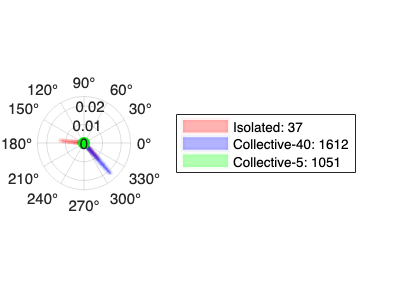


figure
polarhistogram(psi_mat_isolated,500,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[1 0 0],'EdgeAlpha',0.05,'EdgeColor',[1 0 0],'LineWidth',3)    %red
hold on 
polarhistogram(psi_mat_collective,500,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[0 0 1],'EdgeAlpha',0.05,'EdgeColor',[0 0 1],'LineWidth',3)      %blue
polarhistogram(psi_mat_semicollective,500,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[0 1 0],'EdgeAlpha',0.05,'EdgeColor',[0 1 0],'LineWidth',3)      %blue
% legend_isol = sprintf("Isolated: %d",tot_n_even_isol); 
% legend_col = sprintf("Collective: %d",tot_n_even_col);
% legend_semicol = sprintf("Semi-collective: %d",tot_n_even_semicol);
legend({legend_isol, legend_col,legend_semicol})


% ind = 1; 
% name = sprintf('dataSet_%d', 2);
% figure
% histogram(psi.(name){ind},10,'Normalization','probability')
% xlim([-180, 180]);
% xticks(-180:90:180);
% xlabel('$\psi$ (deg)','Interpreter','latex')
% ylabel('prob.','Interpreter','latex')

% figure 
% plot(psi.(name){ind},'-')
% ylim([-180, 180]);
% yticks(-180:90:180);
% xlabel('time','Interpreter','latex')
% ylabel('$\psi$ (deg)','Interpreter','latex')
% axis tight 

`Expectation: uniform distribution through all angles. Not sure why but I get a large number of trajectories that have peaks at 90 deg. I am not still sure if this is due to an error in my computations or some problems in the data set! Checking! `


$$\Delta \psi \left(t\right):\textrm{allignment}$$


- `allignemnt of the worm direction of movement (bearing) and the worm body orientation `

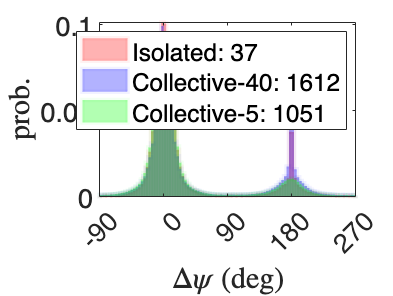

for k = 1:numFiles+numFiles2+numFiles3
    name = sprintf('dataSet_%d', k); %
    delta_psi(1).(name) = [];

    for i =1:size(worm_index_kept.(name),1)
        delta_psi.(name){i,1} = (phi.(name){i} - psi.(name){i});
        for j = 1:size(delta_psi.(name){i},1)   % ask greg if htis makes sense! not sure how to wrap between -90 and 270
            if delta_psi.(name){i}(j) < -90
                delta_psi.(name){i}(j) = abs(delta_psi.(name){i}(j)); 
            end 
            if delta_psi.(name){i}(j) > 270 
                delta_psi.(name){i}(j) = delta_psi.(name){i}(j) -360;
            end 
        end 
    end 
end 

delta_psi_mat_isolated = []; 
delta_psi_mat_collective = [];
delta_psi_mat_semicollective = [];

for k = 1:numFiles
    name = sprintf('dataSet_%d', k);
    delta_psi_mat_isolated = [delta_psi_mat_isolated; cell2mat(delta_psi.(name))];
end 
for k = numFiles + 1:numFiles2+numFiles
    name = sprintf('dataSet_%d', k); 
    delta_psi_mat_collective = [delta_psi_mat_collective; cell2mat(delta_psi.(name))];
end 
for k = numFiles2+numFiles+1 : numFiles2+numFiles3+numFiles
    name = sprintf('dataSet_%d', k); 
    delta_psi_mat_semicollective = [delta_psi_mat_semicollective; cell2mat(delta_psi.(name))];
end 
delta_psi_mat_isolated(isnan(delta_psi_mat_isolated)) = [];
delta_psi_mat_collective(isnan(delta_psi_mat_collective)) = []; 
delta_psi_mat_semicollective(isnan(delta_psi_mat_semicollective)) = [];

figure
histogram(delta_psi_mat_isolated,100,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[1 0 0],'EdgeAlpha',0.05,'EdgeColor',[1 0 0],'LineWidth',3)     %red
hold on 
histogram(delta_psi_mat_collective,100,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[0 0 1],'EdgeAlpha',0.05,'EdgeColor',[0 0 1],'LineWidth',3)   %blue
histogram(delta_psi_mat_semicollective,100,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[0 1 0],'EdgeAlpha',0.05,'EdgeColor',[0 1 0],'LineWidth',3)   %blue
xlim([-90, 270]);
xticks(-90:90:270);
xlabel('$\Delta \psi$ (deg)','Interpreter','latex')
ylabel('prob.','Interpreter','latex')
axis tight
legend({legend_isol, legend_col,legend_semicol})

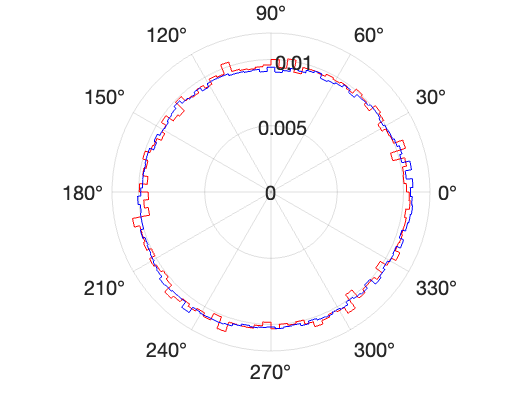


figure
polarhistogram(delta_psi_mat_isolated,100,'Normalization','probability','DisplayStyle','stairs','EdgeColor',[1 0 0])    %red
hold on 
polarhistogram(delta_psi_mat_collective,100,'Normalization','probability','DisplayStyle','stairs','EdgeColor',[0 0 1])      %blue

`Speed with sign distribution: differentiating between forward and backward movment `

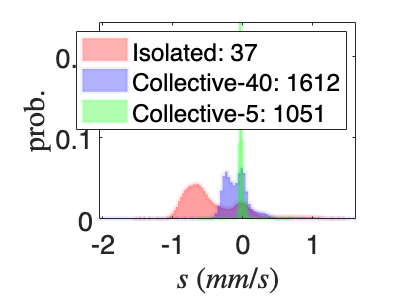

clear forward
for k = 1:numFiles+numFiles2+numFiles3
    name = sprintf('dataSet_%d', k );
     for i = 1:size(worm_index_kept.(name),1)  
         forward.(name){i,1} = boolean(delta_psi.(name){i} > 90);
         forward.(name){i,1} = double(forward.(name){i,1});
         forward.(name){i,1}(find(forward.(name){i,1} == 0),1) = -1;        
         speed_sign.(name){i,1} = speed_centr.(name){i}.*forward.(name){i};
     end 
     ang_diff = []; 
end 

speed_centr_mat_isolated_sign = []; 
speed_centr_mat_collective_sign = []; 
speed_centr_mat_semicollective_sign = []; 

for k = 1:numFiles
    name = sprintf('dataSet_%d', k);
    speed_centr_mat_isolated = [speed_centr_mat_isolated; cell2mat(speed_centr.(name))];
    speed_centr_mat_isolated_sign = [speed_centr_mat_isolated_sign; cell2mat(speed_sign.(name))];
end 
for k = numFiles+1:numFiles+numFiles2
    name = sprintf('dataSet_%d', k);
    speed_centr_mat_collective = [speed_centr_mat_collective; cell2mat(speed_centr.(name))];
    speed_centr_mat_collective_sign = [speed_centr_mat_collective_sign; cell2mat(speed_sign.(name))];
end 
for k = numFiles2+numFiles+1 : numFiles2+numFiles3+numFiles
    name = sprintf('dataSet_%d', k);
    speed_centr_mat_semicollective = [speed_centr_mat_semicollective; cell2mat(speed_centr.(name))];
    speed_centr_mat_semicollective_sign = [speed_centr_mat_semicollective_sign; cell2mat(speed_sign.(name))];
end 

% plot histogram speed all trajectories
figure
h1 = histogram(speed_centr_mat_isolated_sign,100,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[1 0 0],'EdgeAlpha',0.05,'EdgeColor',[1 0 0],'LineWidth',3);       %red
hold on 
h2 = histogram(speed_centr_mat_collective_sign,100,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[0 0 1],'EdgeAlpha',0.05,'EdgeColor',[0 0 1],'LineWidth',3);     %blue
h3 = histogram(speed_centr_mat_semicollective_sign,100,'Normalization','probability','FaceAlpha',0.3,'FaceColor',[0 1 0],'EdgeAlpha',0.05,'EdgeColor',[0 1 0],'LineWidth',3);       % green
axis tight
xlabel('$s$ $(mm/s)$','Interpreter','latex')
ylabel('prob.','Interpreter','latex')
% xlim([0, 4]);
% ylim([0, 0.4]);
legend({legend_isol, legend_col,legend_semicol})

`The distribution is as expected with a large peak at 0 indiccating forward crawling and a peak at 180 for backward crawling. The only anomaly that is not in Antonio's results, is a minor peak at 90 and -90. The result is peculiar becuase it would mean that the worm is moving side ways, as if exibiting a rolling behaviour like in drosophila larvas. `

## `MSD`

traj_length_isolated = []; 
traj_length_collective = []; 
traj_length_semicollective = []; 

for k = 1:numFiles
    name = sprintf('dataSet_%d', k); %
    for i = 1:size(rows_worm_i_used.(name),1)
        traj_length_isolated = [traj_length_isolated; size(rows_worm_i_used.(name){i},1)];
    end
end 
for k = numFiles+1:numFiles+numFiles2
    name = sprintf('dataSet_%d', k); %
    for i =1:size(rows_worm_i_used.(name),1)
        traj_length_collective = [traj_length_collective; size(rows_worm_i_used.(name){i},1)];
    end
end 
for k = numFiles2+numFiles+1 : numFiles2+numFiles3+numFiles
    name = sprintf('dataSet_%d', k); %
    for i =1:size(rows_worm_i_used.(name),1)
        traj_length_semicollective = [traj_length_semicollective; size(rows_worm_i_used.(name){i},1)];
    end
end 

max_traj_length_isolated = max(traj_length_isolated); 
max_traj_length_collective = max(traj_length_collective);
max_traj_length_semicollective = max(traj_length_semicollective);

% ind = 3
% name = sprintf('dataSet_%d', 23);
% % figure 
% % plot(xy_coor.(name){ind}(:,1), xy_coor.(name){ind}(:,2),'b.-')
% % axis equal 
% trajData.(name).frame_number(rows_worm_i_used.(name){ind}(1))
% trajData.(name).frame_number(rows_worm_i_used.(name){ind}(end))
% trajData.(name).worm_index_joined(rows_worm_i_used.(name){ind}(end))

`Estimate MSD terms for all data sets and all individuals`

clear MSD_terms
for k = 1:numFiles+numFiles2+numFiles3
    name = sprintf('dataSet_%d', k); %
    for i=1:size(worm_index_kept.(name),1)%      % loop through all index in data set 
        xy_centrioid_selcted = []; 
        xy_0 = []; 
        
        xy_centrioid_selcted = xy_coor.(name){i,1};
        % VECTOR OF N ENTRIES CONTAINING INITIAL POSITION (MAKES ESTIMATE FASTER) 
        xy_0 = ones(size(xy_centrioid_selcted,1),2).*xy_centrioid_selcted(1,:);     % initial position of trajectory
    
        MSD_terms.(name){i,1} = sum(((xy_centrioid_selcted - xy_0).^2),2); 
    end 
end 

`Use zero padding to make all individuals trajectory of same length `

%isolated padding
for k = 1:numFiles
    name = sprintf('dataSet_%d', k); %
    for i=1:size(worm_index_kept.(name),1)% 
        padd_length = max_traj_length_isolated - size(MSD_terms.(name){i},1);
        MSD_terms.(name){i} = [MSD_terms.(name){i}; NaN(padd_length,1)];
        padd_length = [];
    end   
end

%collective padding
for k = numFiles+1:numFiles+numFiles2
    name = sprintf('dataSet_%d', k); %
    for i=1:size(worm_index_kept.(name),1)% 
        padd_length = max_traj_length_collective - size(MSD_terms.(name){i},1);
        MSD_terms.(name){i} = [MSD_terms.(name){i}; NaN(padd_length,1)];
        padd_length = []; 
    end   
end

%semicollective padding
for k = numFiles2+numFiles+1 : numFiles2+numFiles3+numFiles
    name = sprintf('dataSet_%d', k); %
    for i=1:size(worm_index_kept.(name),1)% 
        padd_length = max_traj_length_semicollective - size(MSD_terms.(name){i},1);
        MSD_terms.(name){i} = [MSD_terms.(name){i}; NaN(padd_length,1)];
        padd_length = []; 
    end   
end

% isolated
MSD_concat_all = [];
for k = 1:numFiles
    name = sprintf('dataSet_%d', k); %
    MSD_terms_concat_isol(1).(name) = [];
    for i =1:size(worm_index_kept.(name),1)
        MSD_terms_concat_isol.(name) = [MSD_terms_concat_isol.(name), MSD_terms.(name){i}];
    end
    MSD_concat_all = [MSD_concat_all, MSD_terms_concat_isol.(name)];
end 

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

MSD_mean_isolated = nanmean(MSD_concat_all,2); 

% collective
MSD_concat_all = [];
for k = numFiles+1:numFiles+numFiles2
    name = sprintf('dataSet_%d', k); %
    MSD_terms_concat_col(1).(name) = [];
    for i =1:size(worm_index_kept.(name),1)
        MSD_terms_concat_col.(name) = [MSD_terms_concat_col.(name), MSD_terms.(name){i}];
    end
    MSD_concat_all = [MSD_concat_all, MSD_terms_concat_col.(name)];
end 
MSD_mean_collective = nanmean(MSD_concat_all,2); 

% semicollective
MSD_concat_all = [];
for k = numFiles2+numFiles+1 : numFiles2+numFiles3+numFiles
    name = sprintf('dataSet_%d', k); %
    MSD_terms_concat_semicol(1).(name) = [];
    for i =1:size(worm_index_kept.(name),1)
        MSD_terms_concat_semicol.(name) = [MSD_terms_concat_semicol.(name), MSD_terms.(name){i}];
    end
    MSD_concat_all = [MSD_concat_all, MSD_terms_concat_semicol.(name)];
end 
MSD_mean_semicollective = nanmean(MSD_concat_all,2); 

MSD_terms.(name){i}

ans = 10796×1 single column vector
1.0e+03 *

         0
    0.0002
    0.0005
    0.0009
    0.0010
    0.0027
    0.0040
       NaN
    0.0051
    0.0069


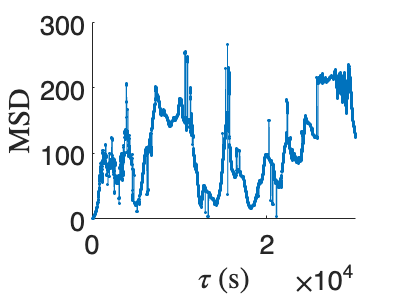

% MSD plot 
figure 
% loglog(MSD_mean_isolated,'.-')
hold on 
% loglog(MSD_mean_collective,'.-')
loglog(MSD_mean_semicollective,'.-')
xlabel('$\tau$ (s)','Interpreter','latex')
ylabel('MSD','Interpreter','latex')

% axis tight